close all
clear all

%rng(80)
%Map setup
%Ez még nem általános minden magasságra, csak ami 3 emelet magas
Env = RLEnv(10,10,4)

Env =   RLEnv with properties:

     Q_Table: [10×10×4 double]
    MapTable: [10×10×4 double]


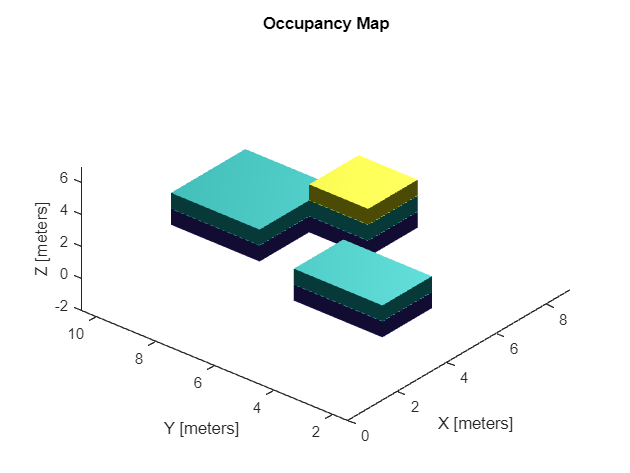

MapOccupancy = occupancyMap3D;
Env.RLAddObstacle(2,3,2,4,1,2,MapOccupancy)
Env.RLAddObstacle(5,6,5,6,1,3,MapOccupancy)
Env.RLAddObstacle(3,5,7,9,1,2,MapOccupancy)
Env.RLAddEndSate(8, 8, 4, 100)
show(MapOccupancy)


%Agent Setup
obsX = 1;
obsY = 1;
obsZ = 1;
Agent = RLAgent(obsX, obsY, obsZ)

Agent =   RLAgent with properties:

       InitRow: 1
       InitCol: 1
     InitDepth: 1
    AgentState: [1 1 1]
       Q_Table: [3×3×3 double]
      MapTable: [3×3×3 double]


EndState = [8 8 4]

EndState =      8     8     4


%RL Computations setup
Env.Q_Table

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0     0     0
     0  -Inf  -Inf  -Inf     0     0     0     0     0     0
     0  -Inf  -Inf  -Inf     0     0  -Inf  -Inf  -Inf     0
     0     0     0     0     0     0  -Inf  -Inf  -Inf     0
     0     0     0     0  -Inf  -Inf  -Inf  -Inf  -Inf     0
     0     0     0     0  -Inf  -Inf     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0     0     0
     0  -Inf  -Inf  -Inf     0     0     0     0     0     0
     0  -Inf  -Inf  -Inf     0     0  -Inf  -Inf  -Inf     0
     0     0     0     0     0     0  -Inf  -Inf  -Inf     0
     0     0     0     0  -Inf  -Inf  -Inf  -Inf  -Inf     0
     0     0     0     0  -Inf  -Inf     0     0 

RL = RLClass(0.01, 0.7, 0.8, EndState, Env.Q_Table)

RL =   RLClass with properties:

    LearningRate: 0.0100
           Gamma: 0.7000
         epsilon: 0.8000
        EndState: [8 8 4]
         Q_Table: [10×10×4 double]


%Setup the Required Datas
ExistingData = [];
Steps = [];
All_cost = [];
costValue = 0;
FinalRoute = [];

%Train the algorithm
tic
for k=1:60
    i = 0;
    Agent.RLReset();
    Agent.AgentState;
    obsX =  Agent.AgentState(1);
    obsY =  Agent.AgentState(2);
    obsZ =  Agent.AgentState(3);
    ExistingData = [];
    while true
        [next_state, reward, done, ExistingData, Goal] = RL.lepes(obsX, obsY, obsZ, Agent.AgentState, ExistingData);
        
        [cost, Q_Table] = RL.learn(obsX, obsY, obsZ, reward, next_state);
        costValue = costValue + cost;
        
        obsX = next_state(1);
        obsY = next_state(2);
        obsZ = next_state(3);
        Agent.AgentState = next_state;
        i = i+1;
        if done
            Steps = [Steps; i];
            All_cost = [All_cost;costValue];
            break
        end
    end
    
    %Itt majd még meg kell különböztetni azt a lehetőséget amikor amiatt
    %lett vége mert elérte a célt, illetve azt amikor amiatt lett vége
    %mert akaádlyba ütközött
    if isempty(FinalRoute) && Goal
        FinalRoute = ExistingData;
    elseif size(ExistingData,1) < size(FinalRoute, 1) && Goal
        FinalRoute = ExistingData;
    end
end
Q_Table

Q_Table = Q_Table(:,:,1) =

       NaN      -Inf   -0.0020   -0.0016      -Inf   -0.0004   -0.0004   -0.0002         0         0
      -Inf      -Inf      -Inf      -Inf   -0.0006   -0.0004   -0.0004   -0.0002         0         0
      -Inf      -Inf      -Inf      -Inf   -0.0006   -0.0004      -Inf      -Inf      -Inf         0
   -0.0008   -0.0006   -0.0004      -Inf   -0.0004      -Inf      -Inf      -Inf      -Inf         0
      -Inf       NaN   -0.0004   -0.0004      -Inf      -Inf      -Inf      -Inf      -Inf         0
      -Inf      -Inf   -0.0002      -Inf      -Inf      -Inf         0         0         0         0
         0         0   -0.0002   -0.0002         0         0         0         0         0         0
         0         0   -0.0002         0         0   -0.0002         0         0         0         0
   -0.0002   -0.0002         0         0   -0.0002         0         0         0         0         0
   -0.0002   -0.0004         0   -0.0002         0         0   

ExistingData

ExistingData =      1     2     1


FinalRoute

FinalRoute =      2     1     2
     1     2     3
     2     3     4
     3     4     4
     4     5     4
     4     5     4
     3     6     3
     3     6     3
     4     6     4
     5     6     4


All_cost

All_cost =   -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
  -Inf
   NaN
   NaN
   NaN


Steps

Steps =     29
    20
     6
    12
    19
    18
     1
    14
    12
     7


toc

Elapsed time is 0.202662 seconds.


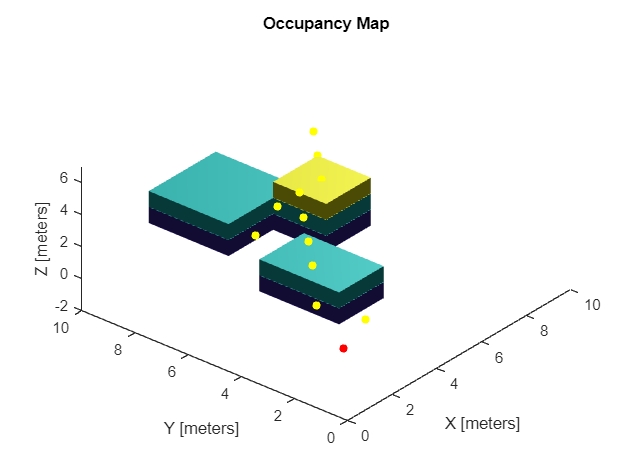

%Plot the Data
f1 = figure('Name','QAgent is learning');
figure(f1);
show(MapOccupancy)
hold on
scatter3(1,1,1,30,"red","filled")
scatter3(8,8,4,30,"blue","filled")
xlim([0 10])
ylim([0 10])
scatter3(FinalRoute(:,1),FinalRoute(:,2),FinalRoute(:,3),30,"yellow","filled")

test
%rng(85)

% Q_Table = zeros(5,5,3);
% MapTable = Q_Table;
% 
% 
% 
% %End State
% Q_Table(end, end, 3) = 100;
% 
% %Obstace
% Q_Table(2:3, 2:4,1:2) = -Inf;
% MapTable(2:3, 2:4, 1:2) = 1;
% 
% [xobstacle, yobstacle, zobstacle] = meshgrid(2:3, 2:4, 1:2);
% xyzObs = [xobstacle(:) yobstacle(:) zobstacle(:)];
% MapOccupancy = occupancyMap3D;
% setOccupancy(MapOccupancy, xyzObs, 1)


obsX = 1;
obsY = 1;
obsZ = 1;


Q_Table;
ExistingData = [];

Steps = [];
All_cost = [];

RL = RLClass(0.01, 0.7, 2, Q_Table, AgentState)

costValue = 0;
i = 0;
for k=1:3
    obsX = 1;
    obsY = 1;
    obsZ = 1;

    AgentState = [1 1 1];
    while true
        [next_state, reward, done, ExistingData] = RL.lepes(obsX, obsY, obsZ, AgentState, ExistingData);
        
        [cost, Q_Table] = RL.learn(obsX, obsY, obsZ, reward, next_state);
        costValue = costValue + cost;
        
        obsX = next_state(1);
        obsY = next_state(2);
        obsZ = next_state(3);
        AgentState = next_state;
        i = i+1;
        if done
            Steps = [Steps; i];
            All_cost = [All_cost;i];
            break
        end
    end
end
Q_Table
ExistingData
All_cost
Steps



%Q_Transition(AgentState(1), AgentState(2), AgentState(3)) = -Inf

%Ezt itt a teszt
%------------------------------------------------------------------
% while true
%SurroundingMatrix = MatrixExtraction(obsX, obsY, obsZ, Q_Transition)
%AgentState = RandomStep(AgentState, SurroundingMatrix)
% 
%     maxValue = max(SurroundingMatrix(:));
% 
%     %[max_value, max_linear_index] = max(SurroundingMatrix(:))
%     [row, col, page] = ind2sub(size(SurroundingMatrix), find(SurroundingMatrix == maxValue));
%     MaxValueIndexes = [row col page];
%     randomRowIndex = randi(size(MaxValueIndexes, 1));
%     randomRow = MaxValueIndexes(randomRowIndex, :)
% 
% 
%     AgentState
%     %Azok az értékek ahol a bal kezdő sarokban van
%     if AgentState(1) == 1 && AgentState(3)==1 && AgentState(2) == 1
%         localCenter = [1 1 1]
%     elseif AgentState(1) == 1 && AgentState(2) == 1 && AgentState(3)==2
%         localCenter = [1 1 2]
%     elseif AgentState(1) == 1 && AgentState(2) == 1 && AgentState(3)==3
%         localCenter = [1 1 3]
% 
%     %Amik az első emeleten a falon vannak
%     elseif AgentState(1) == 1 && AgentState(3)==1
%         localCenter = [1 2 1]
%     elseif AgentState(2) == 1 && AgentState(3)==1
%         localCenter = [2 1 1] 
% 
%     %Amik a második emeleten a falon vannak
%     elseif AgentState(2) == 1 && AgentState(3)==2
%         localCenter = [2 1 2]
%     elseif AgentState(1) == 1 && AgentState(3)==2
%         localCenter = [1 2 2]
% 
%     %Amik a haramik emeleten a falon vannak
%     elseif AgentState(2) == 1 && AgentState(3)==3
%         localCenter = [2 1 3]
%     elseif AgentState(1) == 1 && AgentState(3)==3
%         localCenter = [1 2 3]
% 
%     %Amik nincsenek falon 
%     elseif AgentState(3) == 1
%         localCenter = [2 2 1]
%     elseif AgentState(3) == 3
%         localCenter = [2 2 3]
%     else
%         localCenter = [2 2 2]
%     end
%     globalCenter = AgentState;
%     offset = globalCenter - localCenter
%     AgentState = randomRow + offset
% 
% 
%     obsX = AgentState(1);
%     obsY = AgentState(2);
%     obsZ = AgentState(3);
%     ExistingData = [ExistingData;AgentState]
% 
%     if isequal(AgentState, [3 3 3])
%         break
%     end
% 
%     Q_Transition(AgentState(1), AgentState(2), AgentState(3)) = -Inf
% end
%-----------------------------------------------

%Plot the Data
f1 = figure('Name','QAgent is learning');
figure(f1);
show(MapOccupancy)
hold on
scatter3(1,1,1,30,"red","filled")
scatter3(5,5,1,30,"blue","filled")
xlim([0 5])
ylim([0 5])


costValue = 0;
while true
   
    %Q_Table(obsX, obsY, obsZ);

   

    [next_state, reward, done, ExistingData] = step(obsX, obsY, obsZ, Q_Table, AgentState, ExistingData);
    [cost, Q_Table] = learn(obsX, obsY, obsZ, reward, next_state, Q_Table);
    costValue = costValue + cost;
    obsX = next_state(1);
    obsY = next_state(2);
    obsZ = next_state(3);
    AgentState = next_state;
    figure(1);
    scatter3(ExistingData(end,1),ExistingData(end,2),ExistingData(end,3),30,"yellow","filled")
    drawnow
    if done
        break
    end
    
end
Q_Table
ExistingData

function [next_state, reward, done, ExistingData] = step(obsx, obsy, obsz, Q_Table, AgentState,ExistingData)
    epsilon = 2; %Azért kettő mert biztosra megyünk, hogy abba menjen bele ahova kell
    r = rand(1);
    if r < epsilon
        SurroundingMatrix = MatrixExtraction(obsx, obsy, obsz, Q_Table);
    
        
        maxValue = max(SurroundingMatrix(:));
        [row, col, page] = ind2sub(size(SurroundingMatrix), find(SurroundingMatrix == maxValue));
        MaxValueIndexes = [row col page];
        randomRowIndex = randi(size(MaxValueIndexes, 1));
        randomRow = MaxValueIndexes(randomRowIndex, :);
        localCenter = CenterData(AgentState);
        
        TransformationData = randomRow -localCenter
        AgentState = AgentState + TransformationData
        
        
        %globalCenter = AgentState;
        %offset = globalCenter - localCenter;
        %AgentState = randomRow + offset;
        
        

        %Ide beimplementálni, hogy elérte-e a célt vagy nem, illetve, hogy
        %ütközött-e
        if isequal(AgentState, [5 5 3])
            next_state = AgentState;
            reward = 100;
            done = true;
            "Elértem a 100-at"
        elseif Q_Table(AgentState(1), AgentState(2), AgentState(3)) == -Inf
            next_state = AgentState;
            reward = -100;
            done = true;
        else
            next_state = AgentState;
            reward = -0.02;
            done = false;
        end
        ExistingData = [ExistingData;AgentState];
    else    
        SurroundingMatrix = MatrixExtraction(obsx, obsy, obsz, Q_Table);
        AgentState = RandomStep(AgentState, SurroundingMatrix);
        if isequal(AgentState, [5 5 1])
            next_state = AgentState;
            reward = 100;
            done = true;
        elseif Q_Table(AgentState(1), AgentState(2), AgentState(3)) == -Inf
            next_state = AgentState;
            reward = -100;
            done = true;
        else
            next_state = AgentState;
            reward = -0.02;
            done = false;
        end
        ExistingData = [ExistingData;AgentState];
    end
end
function [cost, Q_Table] = learn(obsx, obsy, obsz, reward, next_state, Q_Table)
    gamma = 0.9;
    lr = 0.1;
    q_predict = Q_Table(obsx, obsy, obsz);
    q_target = reward + gamma*Q_Table(next_state(1), next_state(2), next_state(3));
    Q_Table(obsx, obsy, obsz) = Q_Table(obsx, obsy, obsz) + lr*(q_target-q_predict);
    cost = Q_Table(obsx, obsy, obsz);
end

function surroundingmatrix = MatrixExtraction(obsx, obsy, obsz, Q_Table)
    matrix_size = size(Q_Table);
    matrix = Q_Table;

    % Generate random row, column, and depth indices within the matrix
    random_row = obsx;
    random_col = obsy;
    random_depth = obsz;

    % Define the size of the surrounding matrix
    surrounding_size = 1;
        
    % Calculate the range for extraction
    row_range = max(1, random_row - surrounding_size):min(matrix_size(1), random_row + surrounding_size);
    col_range = max(1, random_col - surrounding_size):min(matrix_size(2), random_col + surrounding_size);
    depth_range = max(1, random_depth - surrounding_size):min(matrix_size(3), random_depth + surrounding_size);

    % Extract the surrounding matrix
    surroundingmatrix = matrix(row_range, col_range, depth_range);

end


function localCenter = CenterData(AgentState)
     %Azok az értékek ahol a bal kezdő sarokban van
    if AgentState(1) == 1 && AgentState(3)==1 && AgentState(2) == 1
        localCenter = [1 1 1];
    elseif AgentState(1) == 1 && AgentState(2) == 1 && AgentState(3)==2
        localCenter = [1 1 2];
    elseif AgentState(1) == 1 && AgentState(2) == 1 && AgentState(3)==3
        localCenter = [1 1 3];

    %Amik az első emeleten a falon vannak
    elseif AgentState(1) == 1 && AgentState(3)==1
        localCenter = [1 2 1];
    elseif AgentState(2) == 1 && AgentState(3)==1
        localCenter = [2 1 1];

    %Amik a második emeleten a falon vannak
    elseif AgentState(2) == 1 && AgentState(3)==2
        localCenter = [2 1 2];
    elseif AgentState(1) == 1 && AgentState(3)==2
        localCenter = [1 2 2];

    %Amik a haramik emeleten a falon vannak
    elseif AgentState(2) == 1 && AgentState(3)==3
        localCenter = [2 1 2];
    elseif AgentState(1) == 1 && AgentState(3)==3
        localCenter = [1 2 2];

    %Amik nincsenek falon 
    elseif AgentState(3) == 1
        localCenter = [2 2 1];
    %elseif AgentState(3) == 3
    %    localCenter = [2 2 2];
    else
        localCenter = [2 2 2];
    end
end
function AgentStateRandom = RandomStep(AgentState, SurroundingMatrix)
    rows = size(SurroundingMatrix, 1);
    cols = size(SurroundingMatrix, 2);
    depth = size(SurroundingMatrix, 3);
    given_value = [AgentState(1) AgentState(2) AgentState(3)];
    while true
        % Generate random indices
        random_row = randi(rows);
        random_col = randi(cols);
        random_depth = randi(depth);

        % Check if the randomly chosen index is not equal to the given value
        if ~isequal([random_row, random_col, random_depth], given_value)
            % Display the randomly chosen cell index
            AgentStateRandom = [random_row random_col, random_depth];
            break; % Exit the loop if a suitable index is found
        end
    end
end